disp("1.3)");

1.3)



n = 25;
N = 10000;
d = 2;
true_cs = [4, 12, 36, 100, 284, 780, 2172, 5916,...
    16268, 44100, 120292, 324932, 881500, 2374444,...
    6416596, 17245332, 46466676, 124658732, 335116732,... 
    897697164, 2408806028, 6444560484, 17266613812, 46146397316];

steps = [eye(2); -eye(2)];
c_ns = zeros(1, n);

for i=1:n
    N_SA = 0;
    for j=1:N
        walk = zeros(i+1,d);
        for k=1:i
           step = steps(randi(4,1),:);
           walk(k+1,:) = walk(k,:) + step; 
        end
        
        if length(unique(walk, 'rows')) == i+1
            N_SA = N_SA + 1;
        end
    end
    c_n = round((4^i)*(N_SA/N));
    c_ns(i) = c_n;
    if i <= 24
        perc_diff = round(abs(1-(c_n/true_cs(i)))*100, 2);
        disp(i + " & " + c_n + " & " + perc_diff + "\% \\"); % latex format
    end
end

1 & 4 & 0\% \\
2 & 12 & 0\% \\
3 & 36 & 0\% \\
4 & 101 & 1\% \\
5 & 285 & 0.35\% \\
6 & 792 & 1.54\% \\
7 & 2091 & 3.73\% \\
8 & 5806 & 1.86\% \\
9 & 15965 & 1.86\% \\
10 & 42677 & 3.23\% \\
11 & 106535 & 11.44\% \\
12 & 345611 & 6.36\% \\
13 & 818728 & 7.12\% \\
14 & 2174327 & 8.43\% \\
15 & 4187593 & 34.74\% \\
16 & 18897856 & 9.58\% \\
17 & 39513699 & 14.96\% \\
18 & 137438953 & 10.25\% \\
19 & 219902326 & 34.38\% \\
20 & 1099511628 & 22.48\% \\
21 & 1759218604 & 26.97\% \\
22 & 1759218604 & 72.7\% \\
23 & 14073748836 & 18.49\% \\
24 & 84442493013 & 82.99\% \\



for i=1:n-1
    mu = (c_ns(i+1)*i^(11/32))/(c_ns(i)*(i+1)^(11/32));
    disp(i + " & " + mu + " \\");
end

1 & 2.364 \\
2 & 2.6097 \\
3 & 2.5414 \\
4 & 2.6134 \\
5 & 2.6101 \\
6 & 2.5039 \\
7 & 2.6521 \\
8 & 2.6406 \\
9 & 2.5781 \\
10 & 2.4158 \\
11 & 3.1485 \\
12 & 2.3046 \\
13 & 2.5889 \\
14 & 1.8808 \\
15 & 4.4138 \\
16 & 2.0478 \\
17 & 3.4106 \\
18 & 1.5705 \\
19 & 4.9126 \\
20 & 1.5734 \\
21 & 0.98414 \\
22 & 7.8787 \\
23 & 5.9129 \\
24 & 1.3148 \\


disp("1.4)");

1.4)



n = 150;
N = 10000;
d = 2;

steps = [eye(2); -eye(2)];
X = zeros(n+1, d, N);
w = zeros(n+1, N);
w(1,:) = 1;
c_ns = zeros(1, n);

for i=1:n
    for j=1:N
        A = X(1:i, :, j); % history
        b = X(i, :, j); % current position
        free = setdiff(b+steps, A, 'rows');
    
        if isempty(free)
            X(i+1, :, j) = b;
            w(i+1, j) = 0;
        else
            num_pos = size(free, 1);
            X(i+1, :, j) = free(randi(num_pos, 1), :);
            w(i+1, j) = w(i, j) * num_pos;
        end
    end
    c_n = round(mean(w(i+1,:)));
    c_ns(i) = c_n;
    if i <= 24
        perc_diff = round(abs(1-(c_n/true_cs(i)))*100, 2);
        disp(i + " & " + c_n + " & " + perc_diff + "\% \\"); % latex format
    end
end

1 & 4 & 0\% \\
2 & 12 & 0\% \\
3 & 36 & 0\% \\
4 & 100 & 0\% \\
5 & 284 & 0\% \\
6 & 781 & 0.13\% \\
7 & 2180 & 0.37\% \\
8 & 5943 & 0.46\% \\
9 & 16330 & 0.38\% \\
10 & 44187 & 0.2\% \\
11 & 120834 & 0.45\% \\
12 & 327467 & 0.78\% \\
13 & 891177 & 1.1\% \\
14 & 2390893 & 0.69\% \\
15 & 6454514 & 0.59\% \\
16 & 17389141 & 0.83\% \\
17 & 46924087 & 0.98\% \\
18 & 126334095 & 1.34\% \\
19 & 340306893 & 1.55\% \\
20 & 911178382 & 1.5\% \\
21 & 2418865403 & 0.42\% \\
22 & 6474833209 & 0.47\% \\
23 & 17459384965 & 1.12\% \\
24 & 46733014100 & 1.27\% \\



mus = zeros(n-1, 1);

for i=1:n-1
    mus(i) = (c_ns(i+1)*i^(11/32))/(c_ns(i)*(i+1)^(11/32));
    disp(i + " & " + mus(i) + " \\");
end

1 & 2.364 \\
2 & 2.6097 \\
3 & 2.5162 \\
4 & 2.6303 \\
5 & 2.5829 \\
6 & 2.6472 \\
7 & 2.6038 \\
8 & 2.6387 \\
9 & 2.6096 \\
10 & 2.6465 \\
11 & 2.6302 \\
12 & 2.6476 \\
13 & 2.6154 \\
14 & 2.6364 \\
15 & 2.635 \\
16 & 2.6428 \\
17 & 2.6399 \\
18 & 2.6441 \\
19 & 2.6307 \\
20 & 2.6105 \\
21 & 2.6343 \\
22 & 2.6556 \\
23 & 2.6378 \\
24 & 2.6265 \\
25 & 2.6265 \\
26 & 2.632 \\
27 & 2.6219 \\
28 & 2.655 \\
29 & 2.6302 \\
30 & 2.6606 \\
31 & 2.6279 \\
32 & 2.6522 \\
33 & 2.6614 \\
34 & 2.645 \\
35 & 2.6211 \\
36 & 2.6462 \\
37 & 2.6243 \\
38 & 2.6289 \\
39 & 2.6185 \\
40 & 2.6411 \\
41 & 2.6366 \\
42 & 2.646 \\
43 & 2.6471 \\
44 & 2.6464 \\
45 & 2.6463 \\
46 & 2.6615 \\
47 & 2.6779 \\
48 & 2.6775 \\
49 & 2.6568 \\
50 & 2.6276 \\
51 & 2.6477 \\
52 & 2.6095 \\
53 & 2.6685 \\
54 & 2.6369 \\
55 & 2.644 \\
56 & 2.6016 \\
57 & 2.6408 \\
58 & 2.6443 \\
59 & 2.6632 \\
60 & 2.6666 \\
61 & 2.636 \\
62 & 2.6669 \\
63 & 2.6741 \\
64 & 2.6988 \\
65 & 2.6463 \\
66 & 2.6802 \\
67 & 2.6154 \\
68 & 2.6376 


x = 1:n-1;
plot(x, mus);

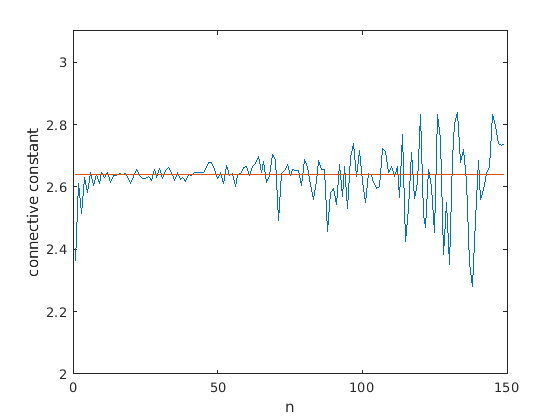

ylim([2, 3.1]);
hold on;
true_mu = 2.64 .* ones(n-1, 1);
plot(x, true_mu);
xlabel('n');
ylabel('connective constant');
hold off;

disp("1.5)");

1.5)



true_cs = [4, 12, 36, 100, 284, 780, 2172, 5916,...
    16268, 44100, 120292, 324932, 881500, 2374444,...
    6416596, 17245332, 46466676, 124658732, 335116732,... 
    897697164, 2408806028, 6444560484, 17266613812, 46146397316];

n = 150;
N = 10000;
d = 2;

steps = [eye(2); -eye(2)];
X = zeros(n+1, d, N);
w = ones(n+1, N);
c_ns = zeros(1, n+1);
c_ns(1) = 1;

for i=1:n
    ind = randsample(N, N, true, w(i,:));
    X(1:i, :, :) = X(1:i, :, ind);
    
    for j=1:N
        A = X(1:i, :, j); % history
        b = X(i, :, j); % current position
        free = setdiff(b+steps, A, 'rows');
    
        if isempty(free)
            X(i+1, :, j) = b;
            w(i+1, j) = 0;
        else
            num_pos = size(free, 1);
            X(i+1, :, j) = free(randi(num_pos, 1), :);
            w(i+1, j) = num_pos;
        end
    end
    
    c_n = round(c_ns(i) * mean(w(i+1, :)));
    c_ns(i+1) = c_n;
    
    if i <= 24
        perc_diff = round(abs(1-(c_n/true_cs(i)))*100, 2);
        disp(i + " & " + c_n + " & " + perc_diff + "\% \\"); % latex format
    end
end

1 & 4 & 0\% \\
2 & 12 & 0\% \\
3 & 36 & 0\% \\
4 & 100 & 0\% \\
5 & 284 & 0\% \\
6 & 785 & 0.64\% \\
7 & 2188 & 0.74\% \\
8 & 5984 & 1.15\% \\
9 & 16433 & 1.01\% \\
10 & 44405 & 0.69\% \\
11 & 120804 & 0.43\% \\
12 & 327270 & 0.72\% \\
13 & 884251 & 0.31\% \\
14 & 2388097 & 0.57\% \\
15 & 6458370 & 0.65\% \\
16 & 17388515 & 0.83\% \\
17 & 46641214 & 0.38\% \\
18 & 124821217 & 0.13\% \\
19 & 334995182 & 0.04\% \\
20 & 901505534 & 0.42\% \\
21 & 2427033199 & 0.76\% \\
22 & 6526292272 & 1.27\% \\
23 & 17489810660 & 1.29\% \\
24 & 46961890603 & 1.77\% \\


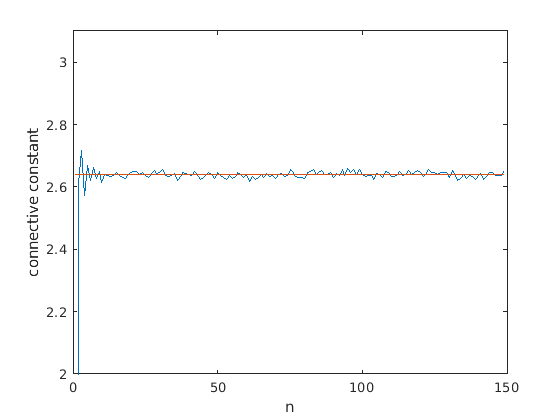


sisr_mus = zeros(n-1, 1);

for i=2:n-1
    sisr_mus(i) = (c_ns(i+1)*i^(11/32))/(c_ns(i)*(i+1)^(11/32));
    % disp(i-1 + " & " + sisr_mus(i) + " \\");
end

x = 1:n-1;
figure;
plot(x, sisr_mus);
ylim([2, 3.1]);
hold on;
true_mu = 2.64 .* ones(n-1, 1);
plot(x, true_mu);
xlabel('n');
ylabel('connective constant');
hold off;

disp("1.6)");

1.6)



A_2s = [];
mu_2s = [];
gamma_2s = [];

for a = 1:10
    n = 100;
    N = 1000;
    d = 2;

    steps = [eye(2); -eye(2)];
    X = zeros(n+1, d, N);
    w = ones(n+1, N);
    c_ns = zeros(1, n+1);
    c_ns(1) = 1;

    for i=1:n
        ind = randsample(N, N, true, w(i,:));
        X(1:i, :, :) = X(1:i, :, ind);
    
        for j=1:N
            A = X(1:i, :, j); % history
            b = X(i, :, j); % current position
            free = setdiff(b+steps, A, 'rows');
    
            if isempty(free)
                X(i+1, :, j) = b;
                w(i+1, j) = 0;
            else
                num_pos = size(free, 1);
                X(i+1, :, j) = free(randi(num_pos, 1), :);
                w(i+1, j) = num_pos;
            end
        end
    
        c_n = round(c_ns(i) * mean(w(i+1, :)));
        c_ns(i+1) = c_n;
    end
    
    Y = log(c_ns(2:end)');
    
    b1 = ones(length(Y), 1); % parameter before log(A2)
    b2 = (1:length(Y))'; % log(mu2)
    b3 = log((1:length(Y))'); % gamma_2 - 1
    
    B = [b1, b2, b3];
    y = B\Y;
   
    A_2s(a) = exp(y(1));
    mu_2s(a) = exp(y(2));
    gamma_2s(a) = y(3) + 1;
end

disp(A_2s);

    1.4512    1.3434    1.3101    1.3756    1.3636    1.4369    1.4706    1.4828    1.5162    1.6140



disp(mu_2s);

    2.6340    2.6461    2.6360    2.6329    2.6435    2.6361    2.6448    2.6349    2.6525    2.6439



disp(gamma_2s);

    1.2831    1.3123    1.3540    1.3224    1.3031    1.2713    1.2604    1.2692    1.2281    1.2065



disp("1.9)");

1.9)


n = 150;
N = 10000;
d = 5;

steps = [eye(d); -eye(d)];
X = zeros(n+1, d, N);
w = ones(n+1, N);
c_ns = zeros(1, n+1);
c_ns(1) = 1;

for i=1:n
    ind = randsample(N, N, true, w(i,:));
    X(1:i, :, :) = X(1:i, :, ind);
    
    for j=1:N
        A = X(1:i, :, j); % history
        b = X(i, :, j); % current position
        free = setdiff(b+steps, A, 'rows');
    
        if isempty(free)
            X(i+1, :, j) = b;
            w(i+1, j) = 0;
        else
            num_pos = size(free, 1);
            X(i+1, :, j) = free(randi(num_pos, 1), :);
            w(i+1, j) = num_pos;
        end
    end
    
    c_n = round(c_ns(i) * mean(w(i+1, :)));
    c_ns(i+1) = c_n;
    
    if i <= 24
        %perc_diff = round(abs(1-(c_n/true_cs(i)))*100, 2);
        disp(i + " & " + c_n + "\\"); % latex format
    end
end

1 & 10\\
2 & 90\\
3 & 810\\
4 & 7209\\
5 & 64245\\
6 & 570637\\
7 & 5068740\\
8 & 44930325\\
9 & 398473573\\
10 & 3534460593\\
11 & 31322743221\\
12 & 277691780026\\
13 & 2458488636104\\
14 & 21765983290883\\
15 & 192705133065833\\
16 & 1706018543031820\\
17 & 1.509860530954021e+16\\
18 & 1.335834006156261e+17\\
19 & 1.180676886341211e+18\\
20 & 1.045276861015601e+19\\
21 & 9.251327386104678e+19\\
22 & 8.181411373901673e+20\\
23 & 7.241858091722804e+21\\
24 & 6.403178506120387e+22\\


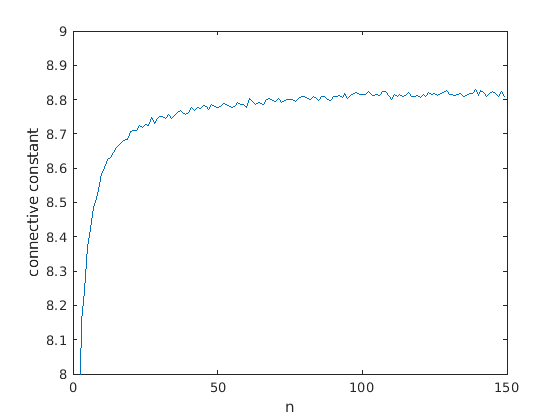


sisr_mus = zeros(n-1, 1);

for i=2:n-1
    sisr_mus(i) = (c_ns(i+1)*i^(11/32))/(c_ns(i)*(i+1)^(11/32));
    % disp(i-1 + " & " + sisr_mus(i) + " \\");
end

x = 1:n-1;
figure;
plot(x, sisr_mus);
ylim([8, 9]);
hold on;
%true_mu = 2.64 .* ones(n-1, 1);
%plot(x, true_mu);
xlabel('n');
ylabel('connective constant');
hold off;

Y = log(c_ns(2:end)');

b1 = ones(length(Y), 1); % parameter before log(A2)
b2 = (1:length(Y))'; % log(mu2)
b3 = log((1:length(Y))'); % gamma_2 - 1
%ind = randsample(length(Y), 20);
ind = 1:1:length(Y);
B = [b1(ind), b2(ind), b3(ind)];
y = B\Y(ind);
   
A_2 = exp(y(1))

A_2 = 1.1459

mu_2 = exp(y(2))

mu_2 = 8.8379

gamma_2 = y(3) + 1

gamma_2 = 1.0241

disp("2)");

2)


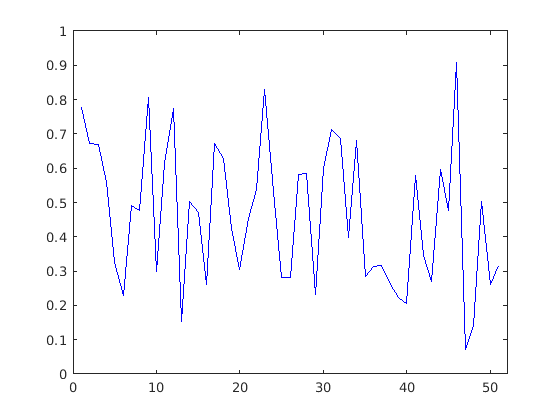

load("population_2023.mat");

N = 1000;
n = 50;
A = 0.9;
B = 3.9;
C = 0.6;
D = 0.99;
G = 0.7;
H = 1.2;
tau = zeros(1,n+1); % vector of filter means
taulower = zeros(1,n+1);
tauupper = zeros(1,n+1);
w = zeros(N,1);
% p = @(x,y) normpdf(y,x,S); % observation density, for weights
p = @(x,y) unifpdf(y,G*x,H*x); % observation density
part = C + (D - C) * rand(N, 1); % initialization
w = p(part,Y(1)); % weighting
tau(1) = sum(part.*w)/sum(w); % estimation
% ------------------- conf int ---------------------------
[xx,I]=sort(part);
cw=cumsum(w(I))/sum(w);
Ilower=find(cw>=0.025,1);
Iupper=find(cw>=0.975,1);
taulower(1)=xx(Ilower);
tauupper(1)=xx(Iupper);
% −−−−−−−------------------------------------------------
ind = randsample(N,N,true,w); % selection
part = part(ind);
for k = 1:n % main loop
    part = (A + (B - A) * rand(N, 1)).*part.*(1-part); % mutation
    w = p(part,Y(k + 1)); % weighting
    tau(k + 1) = sum(part.*w)/sum(w); % estimation
    % ------------------- conf int ---------------------------
    [xx,I]=sort(part); % sort data
    cw=cumsum(w(I))/sum(w); % cumulative normalized weightsum
                            % for sorted data
    Ilower=find(cw>=0.025,1); % index for lower 2.5% quantile
    Iupper=find(cw>=0.975,1); % index upper 2.5% quantile
    taulower(k+1)=xx(Ilower); % lower 2.5% quantile
    tauupper(k+1)=xx(Iupper); % upper 2.5% quantile
    % −−−−−−−------------------------------------------------
    ind = randsample(N,N,true,w); % selection
    part = part(ind);
end

figure;
plot(tau, "blue");
xlim([0 52]);

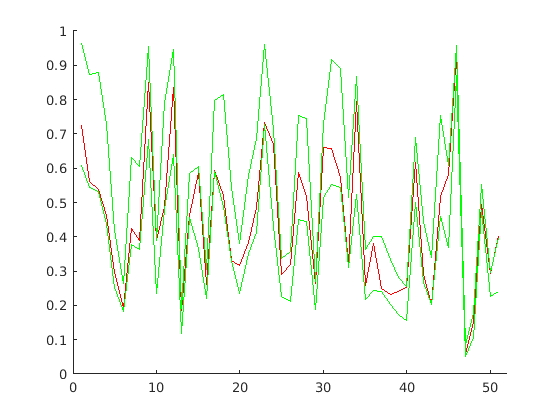

figure;
hold on;
plot(X, "red");
plot(tauupper, "green");
plot(taulower, "green");
xlim([0 52]);